load("PRNList.mat");
IF = 0;
fs = 10.23e6;
time_chip = 0.01;
Ts = 1/fs;
doppler_freq = 5e3;
freq_interval = 5e2;

% read data
fid = fopen('B1C_Signal_IQ_INT8.dat', 'r');
signal = fread(fid, 3 * fs, 'int8');
signal = fread(fid, 2 * fs * time_chip, 'int8');

fclose(fid);

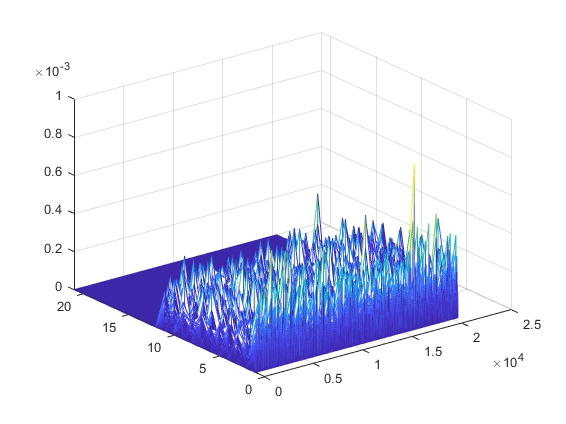


signal_I = signal(1:2:length(signal));
% signal_I = kron(signal_I, ones(2, 1));
signal_Q = signal(2:2:length(signal));
% signal_Q = kron(signal_Q, ones(2, 1));
t = Ts:Ts:time_chip;
res = zeros(21, 20460);
% j = 1;
% maxi = -100;
for PRN = 23:23
    B1C = weil_code_generator(10243, 10230, PRNList(PRN, 2), PRNList(PRN, 3));
    B1C = kron(B1C, ones(1, 10));
%     B1C = repmat(B1C, 1, 10);
    j = 1;
    for freq = IF:freq_interval:IF + doppler_freq
        cos_10ms = cos(2 * pi * freq * t);
        sin_10ms = sin(2 * pi * freq * t);
        signal_Id = signal_Q' .* cos_10ms;
        signal_Qd = signal_Q' .* sin_10ms;
        for i = 1:20460
            B1C = circshift(B1C, 5);
            res(j, i) = ((B1C * signal_Id'/length(B1C)).^2 + (B1C * signal_Qd'/length(B1C)).^2);
        end
        j = j + 1;
    end
    figure;
    mesh(res);
end